# 2 Linear regression with one variable

## 2.1 plotting the data

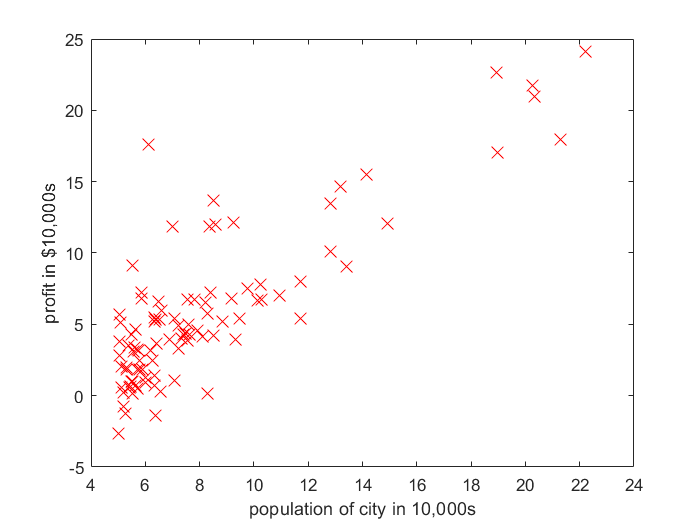

% ex1data1.txt
data = load('./ex1data1.txt');
x = data(:, 1); % 人口
y = data(:, 2); % 利润
m = length(y);
figure;
plot(x, y, 'rx', 'markerSize', 10);
ylabel('profit in $10,000s');
xlabel('population of city in 10,000s');

## 2.2 gradient decent

## 2.2.1 update equations


$$j(\theta) = \frac{1}{2m}\sum_{i=1}^m(h_\theta(x^{(i)}) - y^{(i)})^2\\
h_\theta(x) = \theta^Tx = \theta_01 + \theta_1x_1\\
\theta_j := \theta_j - \alpha\frac{1}{m}\sum_{i=1}^m(h_\theta(x^{(i)}) - y^{(i)})x^{(i)}_j$$


注意 ${x_j }^{\left(i\right)}$ 是对应 $\theta_j$ 的特征数据，这里已经统一用向量思维了

## 2.2.2 implementation

增加一个维度给 x，用于对应 $\theta_0$

X = x; % 保留
x = [ones(m, 1), data(:, 1)];
x

x =     1.0000    6.1101
    1.0000    5.5277
    1.0000    8.5186
    1.0000    7.0032
    1.0000    5.8598
    1.0000    8.3829
    1.0000    7.4764
    1.0000    8.5781
    1.0000    6.4862
    1.0000    5.0546


theta = zeros(2, 1);
theta

theta =      0
     0


iterations = 1500;
alpha = 0.01;

## 2.2.3 computing the cost $j\left(\theta \right)$

compute_cost(x, y, theta)

ans = 32.0727

## 2.2.4 gradient descent

we minimize the value of *J*(*θ*) by changing the values of the vector *θ*, not by changing *X *or *y*  

x

x =     1.0000    6.1101
    1.0000    5.5277
    1.0000    8.5186
    1.0000    7.0032
    1.0000    5.8598
    1.0000    8.3829
    1.0000    7.4764
    1.0000    8.5781
    1.0000    6.4862
    1.0000    5.0546


y

y =    17.5920
    9.1302
   13.6620
   11.8540
    6.8233
   11.8860
    4.3483
   12.0000
    6.5987
    3.8166


theta = [0.11; 0.14]

theta =     0.1100
    0.1400


theta = zeros(2, 1)

theta =      0
     0


h     = x * theta

h =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


cost  = sum(x .* (h - y), 1);
cost.'

ans = 	1.0e+03 *

   -0.5664
   -6.3369


% 理解以上的形状后，谢自定义函数 gd
trained_theta = gd(x, y, 1000, 0.01)

trained_theta =    -3.2414
    1.1273


x * trained_theta

ans =     3.6465
    2.9899
    6.3616
    4.6533
    3.3643
    6.2086
    5.1867
    6.4286
    4.0705
    2.4566


**注意这里 X 和 x 的使用，**X 是一维，x 加入了一个维度

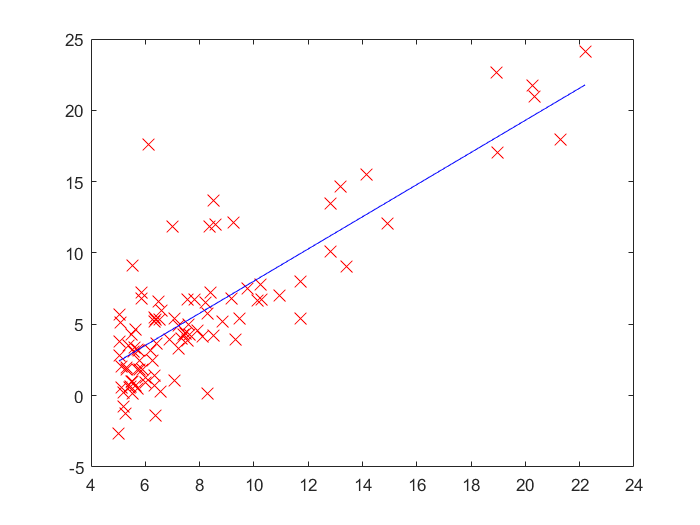

figure;
plot(X, y, 'rx', X, x * trained_theta, 'b', 'MarkerSize', 10);

## 2.4 **Visualizing **$J\left(\theta \right)$

$J\left(\theta \right)$是损失函数，我们可视化损失函数，所以要准备参数和损失量。

% Grid over which we will calculate J
theta0_vals = linspace(-10, 10, 100);
theta1_vals = linspace(-1, 4, 100);

% initialize J_vals to a matrix of 0's
J_vals = zeros(length(theta0_vals), length(theta1_vals));

% Fill out J_vals
for i = 1:length(theta0_vals)
    for j = 1:length(theta1_vals)
	  t = [theta0_vals(i); theta1_vals(j)];
	  J_vals(i,j) = compute_cost(x, y, t);
    end
end

J_vals = J_vals'; % 此处注意

曲线图

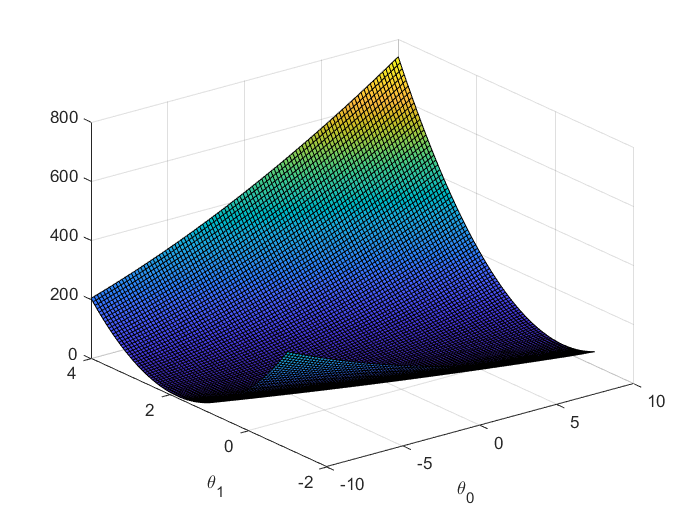

figure;
surf(theta0_vals, theta1_vals, J_vals); % 值为损失量
xlabel('\theta_0'); ylabel('\theta_1'); % 还支持 latex

等高线图

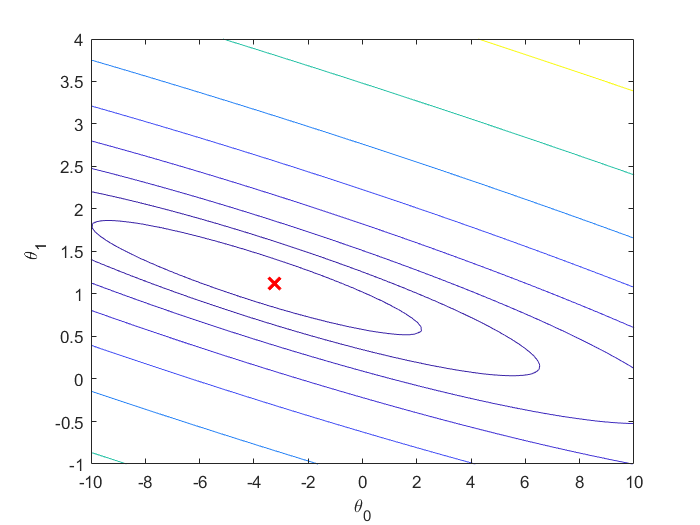

figure;
contour(theta0_vals, theta1_vals, J_vals, logspace(-2, 3, 20));
xlabel('\theta_0'); ylabel('\theta_1');
hold on;
plot(trained_theta(1), trained_theta(2), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
hold off;

# 3. **Linear regression with multiple variables**


$$h_\theta = X\theta = x_1\theta_1 + x_2\theta_2 + ..... x_n\theta_n$$


n 是特征数

## 3.1 **Feature Normalization**

data = load('./ex1data2.txt');

the size of the house,  the number of bedrooms, the price of the house

data

data =         2104           3      399900
        1600           3      329900
        2400           3      369000
        1416           2      232000
        3000           4      539900
        1985           4      299900
        1534           3      314900
        1427           3      198999
        1380           3      212000
        1494           3      242500


发现房屋面积远大于房间数，这样不利于收敛( 这个可以详见李宏毅老师用等高线图的解释

m = mean(data, 1) % 沿着第一维度(行)，不断累加，所以第一维度消失，

m = 	1.0e+05 *

    0.0200    0.0000    3.4041


特征放缩(其实最好要把 mean 和 std 保留)，注意，y 部分也被放缩

% m = mean(data, 1);
% s = std(data, 0, 1);
% X = (data - mean(data, 1)) ./ std(data, 0, 1)
[X, mu_, sigma] = feature_normalize(data)

X =     0.1300   -0.2237    0.4757
   -0.5042   -0.2237   -0.0841
    0.5025   -0.2237    0.2286
   -0.7357   -1.5378   -0.8670
    1.2575    1.0904    1.5954
   -0.0197    1.0904   -0.3240
   -0.5872   -0.2237   -0.2040
   -0.7219   -0.2237   -1.1309
   -0.7810   -0.2237   -1.0270
   -0.6376   -0.2237   -0.7831


mu_ = 	1.0e+05 *

    0.0200    0.0000    3.4041


sigma = 	1.0e+05 *

    0.0079    0.0000    1.2504


## 3.2 **Gradient Descent**

测试一下，与 compute_cost 结果相同

J = computeCostMulti(x, y, theta)

J = 32.0727

用单变量线性回归的数据先测试一下，没有问题

[theta_multi, J_history] = gradientDescentMulti(x, y, theta, 0.01, 1000)

theta_multi =    -3.2414
    1.1273


J_history =     6.7372
    5.9316
    5.9012
    5.8952
    5.8901
    5.8850
    5.8799
    5.8749
    5.8698
    5.8648


这里不用增加额外的全为 1 的列

x_multi = [X(:, 1), X(:, 2)]

x_multi =     0.1300   -0.2237
   -0.5042   -0.2237
    0.5025   -0.2237
   -0.7357   -1.5378
    1.2575    1.0904
   -0.0197    1.0904
   -0.5872   -0.2237
   -0.7219   -0.2237
   -0.7810   -0.2237
   -0.6376   -0.2237


y_multi = X(:, 3)

y_multi =     0.4757
   -0.0841
    0.2286
   -0.8670
    1.5954
   -0.3240
   -0.2040
   -1.1309
   -1.0270
   -0.7831


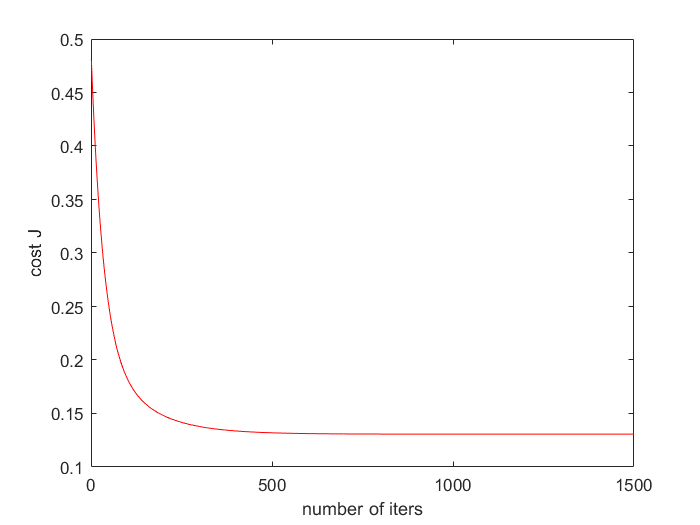

theta = zeros(size(x_multi, 2), 1);
[theta_multi, J] = gradientDescentMulti(x_multi, y_multi, theta, 0.01, 1500);
figure;
plot(1:1500, J(1:1500), 'r');
xlabel('number of iters'); ylabel('cost J');

## 3.2.1 **Optional (ungraded) exercise: Selecting learning rates**

We recommend trying values of the learning rate *α *on a log-scale, at multiplicative steps of about 3 times the previous value

摘自实验 ex1 原文

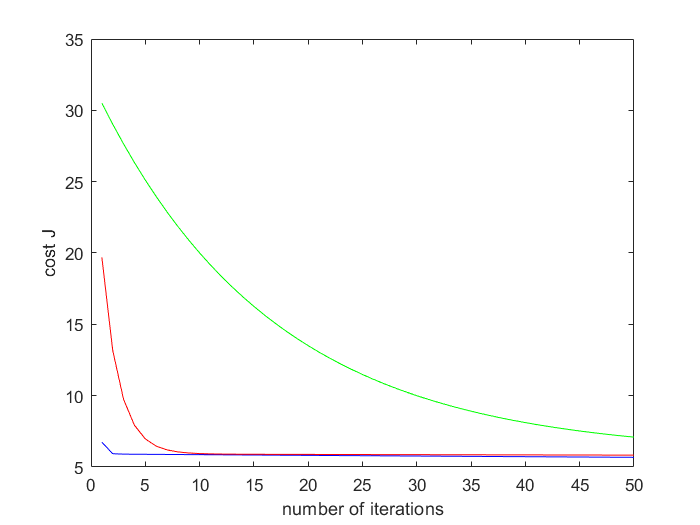

theta = zeros(2, 1);
alpha = 0.01;
num_iters = 1500;
[theta_multi, J1] = gradientDescentMulti(x, y, theta, alpha, num_iters);
plot(1:50, J1(1:50), 'b');
xlabel('number of iterations');
ylabel('cost J');
hold on;
alpha = alpha / 3;
[theta_multi, J2] = gradientDescentMulti(x, y, theta, alpha, num_iters);
plot(1:50, J2(1:50), 'r');
alpha = alpha / 3 / 3;
[theta_multi, J3] = gradientDescentMulti(x, y, theta, alpha, num_iters);
plot(1:50, J3(1:50), 'g');
hold off;

可以看到不同学习率的效果。

但是此处并没有尝试大的学习率的影响，可以预见 cost 反而上涨的结果

## 3.3 **Normal Equations**

add_ones_x_multi = [ones(length(y_multi), 1), x_multi];
perfect_theta = normalEqn(x_multi, y_multi)

perfect_theta =     0.8848
   -0.0532


用梯度下降得到的参数进行预测

theta = zeros(size(x_multi, 2), 1);
[theta_multi, J] = gradientDescentMulti(x_multi, y_multi, theta, 0.01, 1500);
[1650, 3] * theta_multi

ans = 1.4585e+03

用正规方程得到的参数进行预测

[1650, 3] * perfect_theta

ans = 1.4597e+03

## 函数自定义区

function cost = compute_cost(x, y, theta)
    % x .* y 对应元素相乘
    h = x * theta;
    m = length(x);
    c = (h - y) .^ 2;
    cost = sum(c) / (2 * m);
end


$$j(\theta) = \frac{1}{2m}\sum_{i=1}^m(h_\theta(x^{(i)}) - y^{(i)})^2\\
h_\theta(x) = \theta^Tx = \theta_01 + \theta_1x_1\\
\theta_j := \theta_j - \alpha\frac{1}{m}\sum_{i=1}^m(h_\theta(x^{(i)}) - y^{(i)})x^{(i)}_j$$


多注意一下矩阵形状。

% 梯度下降，拟合出参数 
function theta = gd(x, y, iterations, alpha)
    theta = zeros(2, 1);
    m = length(y);
    
    for i = 1 : iterations
        h    = x * theta;
        cost = sum((h - y) .* x, 1); % 沿着列加和，这是第一维度
        theta = theta - alpha * cost.' ./ m; % 不转置会发生广播
    end
end



特征缩放

function [X_norm, mu_, sigma] = feature_normalize(x)
    % 这里还么有
    X_norm = x;
    % 获取平均，标准差
    mu_     = zeros(1, size(x, 2));
    sigma  = zeros(1, size(x, 2));
    
    % mu sigma 都定义好了形状
    % 如果 A 为矩阵，那么 mean(A) 返回包含每列均值的行向量。
    mu_    = mean(x);
    sigma  = std(x);
    
    X_norm = (X_norm - mu_) ./ sigma;
end

J_history 是损失的数组，记录损失变化

PS: 

- sum 尽量用矩阵内积来做

- dev 矩阵计算注意 shape

function [theta, J_history] = gradientDescentMulti(X, y, theta, alpha, num_iters)
    m = length(y);
    J_history = zeros(num_iters, 1); % zero(x) 默认是 x * x 方阵
    for i = 1 : num_iters
        
        theta = theta - alpha / m * X' * (X * theta - y); % 这个更好，用的是矩阵内积
        
        % dev = sum((X * theta - y) .* X, 1); % 注意他的 shape(1, size(X, 2)) 也就是特征数
        % theta = theta - alpha .* dev' ./ m; % theta shape(size(X, 2), 1) 所以要转置
        
        J_history(i, 1) = computeCostMulti(X, y, theta);
    end
end

其实用 compute_cost 也可以，都是直接考虑向量化了。

但 cost 可以写成 $\frac{1}{2m}{\left(X\theta -y\right)}^T \left(X\theta -y\right)$和下式是相同的


$$\frac{1}{2m}\sum_{i=1}^m(h_\theta(x^{(i)}) - y^{(i)})^2\\$$


function J = computeCostMulti(X, y, theta)
    m = length(X);
    J = (X * theta - y)' * (X * theta - y) / (2 * m);
end


无需特征缩放

we still need to add a column of 1’s to the X matrix

function theta = normalEqn(X, y)
    theta = pinv(X' * X) * X' * y;
end